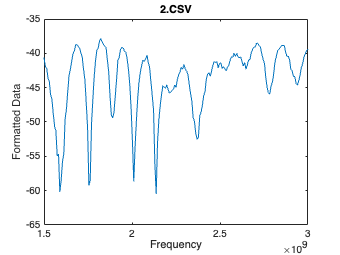

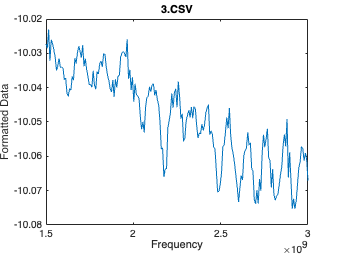

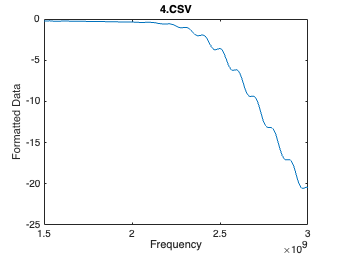

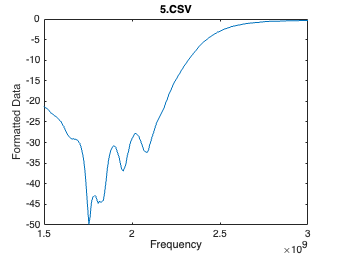

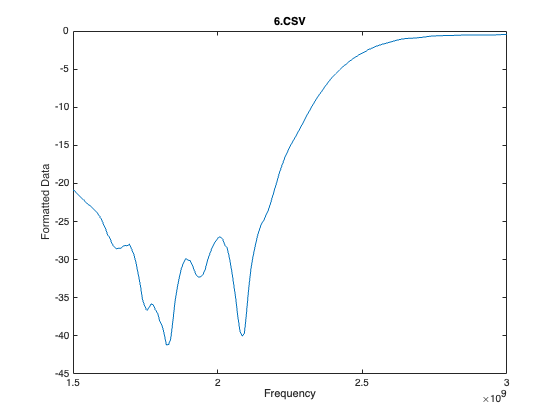

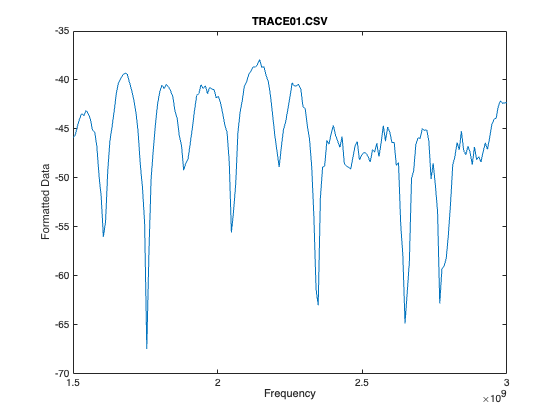

% Set the directory containing the CSV files
directory = '/Users/ohadformanair/Downloads/traces';

% Get a list of all CSV files in the directory
filelist = dir(fullfile(directory, '*.csv'));

% Loop over each file in the directory
for i = 1:length(filelist)
    % Load the data from the current file
    data = readmatrix(fullfile(directory, filelist(i).name), 'HeaderLines', 3);

    % Extract the frequency and formatted data columns
    frequency = data(:, 1);
    formatted_data = data(:, 2);

    % Plot the formatted data as a function of frequency
    figure;
    plot(frequency, formatted_data);
    xlabel('Frequency');
    ylabel('Formatted Data');
    title(filelist(i).name);

    % Save the plot as a PNG file in the same directory as the CSV file
%     [~, filename, ~] = fileparts(filelist(i).name);
%     saveas(gcf, fullfile(directory, [filename '.png']));
end